# Parcial 1. Análisis Numérico y Computación Científica

Juan Manuel Ramirez Osuna

Una de las aplicaciones de la interpolación polinomial consiste en emplear polinomios obtenidos mediante técnicas como polinomios de Lagrange o splines cúbicos. La siguiente es la “función de jorobas integradas” que usa Matlab para demostrar algunas de sus capacidades numéricas: 


$$f(x) = \frac{1}{(x-0.3)^2+0.01}+ \frac{1}{(x-0.9)^2+0.04}$$


La función de jorobas muestra regiones tanto llanas como escarpadas a lo largo de un rango relativamente corto de 𝑥. Genere valores de esta función en el rango de 𝑥 = 0 a 1 y:

syms x
xp = 0:0.04:1

xp =          0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000


yp = 1./((xp-0.3).^2+0.01)+1./((xp-0.9).^2+0.04)

yp =    11.1765   14.1693   18.5270   25.1272   35.4856   51.8868   75.6320   98.5101   98.8106   76.5451   53.4483   37.7583   28.2060   22.5463   19.3133   17.6923   17.2555   17.7889   19.1770   21.2912   23.8462   26.2514   27.6393   27.2880   25.1799   22.0000


fp(x) =  1./((x-0.3).^2+0.01)+1./((x-0.9).^2+0.04)

$$fp(x) = \frac{1}{{\left(x-\frac{9}{10}\right)}^{2}+\frac{1}{25}}+\frac{1}{{\left(x-\frac{3}{10}\right)}^{2}+\frac{1}{100}}$$

fplot(fp)
hold on

1. Ajuste la función mediante polinomios de interpolación de Lagrange comprobando, gráficamente, que la interpolación aproxima de forma adecuada la curva original.

fp1(x) = interpolacion_lagrange(xp,yp)

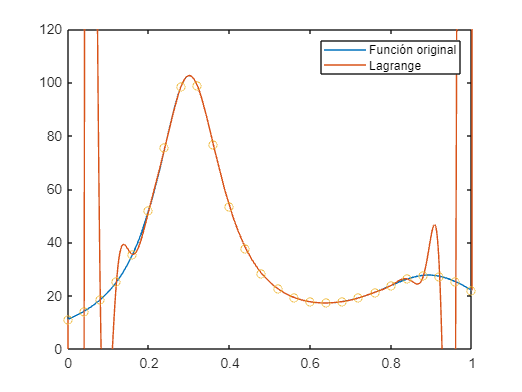

fplot(fp1)
scatter(xp, yp)
xlim([0 1])
ylim([0 120])
legend('Función original', 'Lagrange')
hold off

Graficamente se puede observar que dentro del rango deseado (0 a 1) la interpolacion se asemeja a la funcion objetivo en valores intermedios, al acercarse a los puntos extremos del rango la interpolacion empieza a presentar fuertes fluctuaciones.

2. A partir de la interpolación obtenida, calcule el valor de 𝑥 que se obtiene para 𝑓(𝑥) = 45.

fp2(x) = fp1 - 45

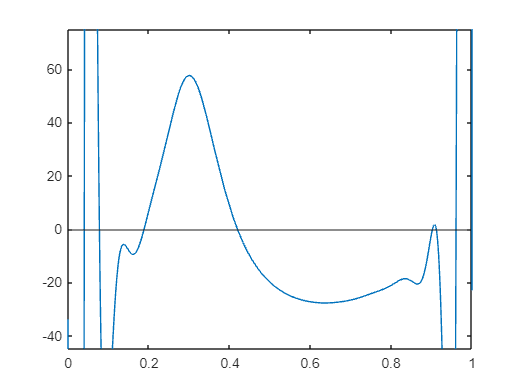

fplot(fp2)
yline(0)
xlim([0 1])
ylim([0-45 120-45])


c2 = falsa_posicion(fp2, 0.25, 0.75, 0.00001)

$$c2 = 0.41920637297724402767660625238388$$

vpa(fp(c2))

$$ans = 44.992799288500177741528660072643$$

Restando el valor deseado a la funcion para realizar una busqueda de raices se emplea el metodo de falsa posicion. Se realiza una busqueda empezando en 0.25 y 0.75 para que la convergencia ocurra en un punto que estable de la interpolacion. De este modo se encuentra que el x deseado se ubica aproximadamente en 0.41919.

3. Usando una estrategia diferente a la del punto 2, calcule el valor de 𝑥 que se obtiene para 𝑓(𝑥) = 22.

fp3(x) = fp1 - 22

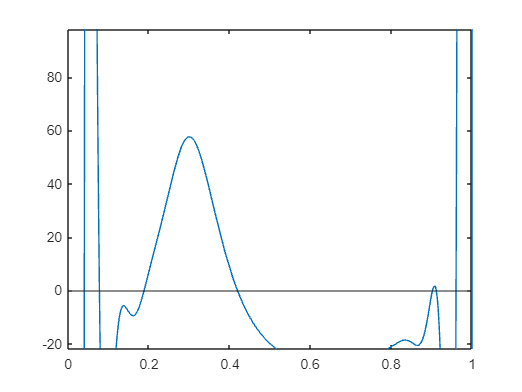

fplot(fp2)
yline(0)
xlim([0 1])
ylim([0-22 120-22])


c3 = newton_raphson(fp3, 0.5, 0.00001)

$$c3 = 0.52529276900637326764145404874785$$

vpa(fp(c3))

$$ans = 22.002122392183131654921116402707$$

Restando el valor deseado a la funcion para realizar una busqueda de raices se emplea el metodo de newton_rahpson. Se realiza una busqueda empezando en 0.5 esperando que al usar un punto medio del rango la pendiente mantenga el valor objetivo entre el dominio deseado. De este modo se encuentra que el x deseado se ubica aproximadamente en 0.5253.